## Large-network Gamma - No Coupling 

### 1. Firing of single networks 

clearvars
% --------------- Parameters of Change: Noise --------------------------
noise_pop='T';
rate_a=0; %frequency of noisy spikes generated in i or e cells
rate_b=0;

connectivity_scaling_within = [1,1,1,1];
connectivity_scaling_between = [0,0,0,0,0,0,0,0];
% (5) Set Connectivity, Connectivity Strength, External Drive, Simulation Duration
load('connectivity_100cell_1_1_nocoupling.mat') 
% (1) simulation time: 
tstop = 300;  % Duration of simulation (msec)
% (2) Define hh_param: for solving HodgkinHuxlkey Equations, using Na, K, l cahnnels and create the 
GNa = 100;           % Maximum sodium current density (mS / cm^2)
GK = 80;             % Maximum potassium current density (mS / cm^2)
Gl = 0.1;            % Leak current density (mS / cm^2)
vNa = 50;            % Reversal potential for sodium current (mV)
vK = -100;           % Reversal potential for potassium current (mV)
vl = -67;            % Reversal potential for leak current (mV)
HH_param = [GNa GK Gl vNa vK vl];  % Load parameter vector
% (3) Define syn_param
Gei=0.2;   % Synaptic strength E-I, default 0.2
Gie=0.2;   % Synaptic strength I-E, default 0.2
Gee=0;     % Synaptic strength E-E, default 0
Gii=0;     % Synaptic strength I-I, default 0
vampa=0;   % reversal potential ampa (noisy input, default 0)
vgaba=-80; % reversal potential gaba (default -80)
syn_param=[Gei Gie Gee Gii vampa vgaba];
% (4) Define stim_param: applied current to inhib and exc cells. Assume inh and exc
% applied currents get activated at the same time. 
del = 0;
dur = tstop;            % Duration of stimulus (msec)
amp_i= 0.5;             % applied current to the i cells, default 0.5
stim_param_i = [del dur amp_i];  % Load parameter vector
amp_e=2.0;              %applied current to the e cells, default 2.0
stim_param_e = [del dur amp_e];  % Load parameter vector
% (6) n, num_exc, num_inh
n = 100;
num_exc = 40; %determines number of I cells
num_inh = 10;

[t,x] = hh_integrate_network_noise_net(tstop, HH_param, syn_param, stim_param_i, stim_param_e,...
connectivity_grid,connectivity_scaling_within,connectivity_scaling_between,n,rate_a, rate_b, noise_pop);

[m, n] = size(x);
AE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)

----------------length of the spike train, m-------------------------


       19619



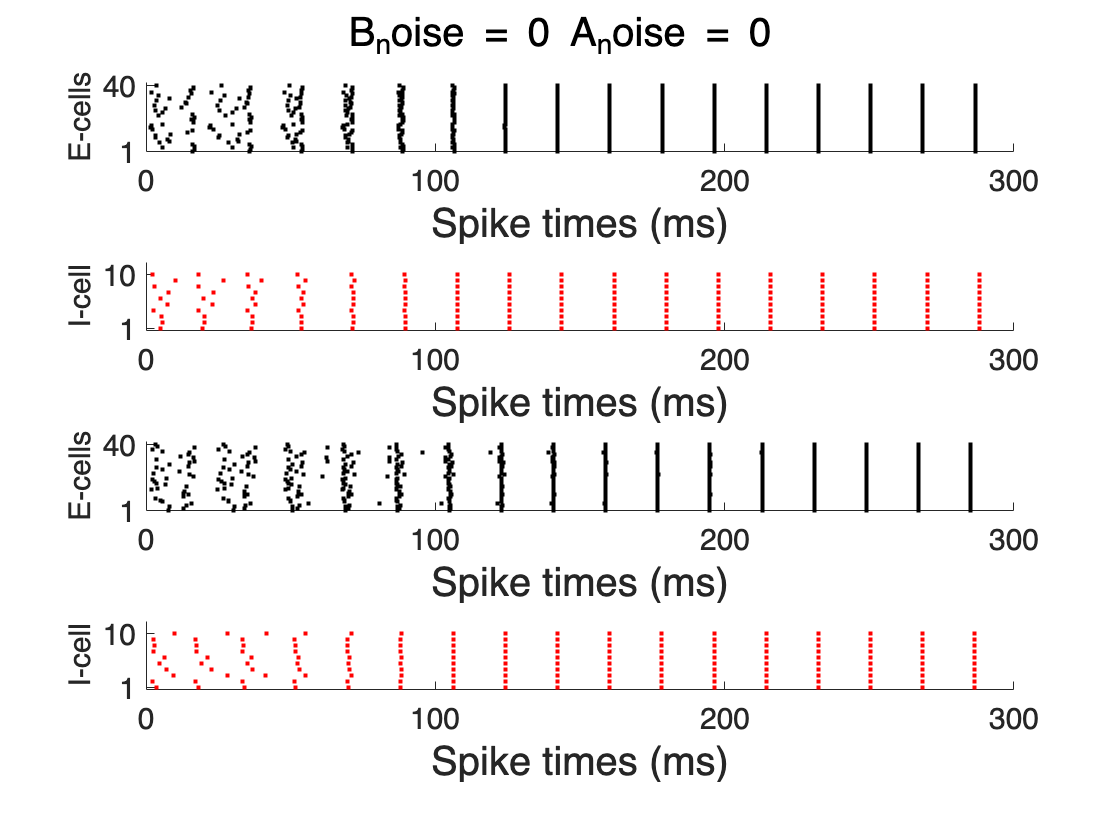

AI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
AE = x(:,1:num_exc); % pop AE
AI = x(:, (num_exc + 1):n); % pop AI

BE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
BI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
BE = x(:,51:num_exc+50); % pop BE
BI = x(:, (num_exc + 51):n); % pop BI

figure
%E cell spiking
subplot(4,1,1)
hold on
Espike_count=0; %will be used to calculate spike rate later
e_count=0; %counts the number of e_cells that actually fire
spike_mat_ae = zeros(num_exc, 25); % hard-coded spike mat, assumes maximum 25 spikes 
for i = 1:num_exc % for each exc cell
    if max(AE(:,i))>0
        [pks,locs] = findpeaks(AE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        % % disp('locs are');
        % % disp(locs);
        num_spikes = length(locs);
        spike_mat_ae(i,1:num_spikes) = locs/100;
        plot(t(locs),i,'k.') %plots cell index vs time of spike
        % index t wth locs, only scatter on those locations for this cell,
        % helps with aligning with the absolute timeframe 
        Espike_count=Espike_count+length(pks);
        e_count=e_count+1;
    end
end

axis([0 tstop .5 num_exc+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_exc-1:num_exc)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('E-cells','Fontsize',15)

%I cell spiking
subplot(4,1,2)
hold on
Ispike_count=0; %used to calculate spike rate later
i_spike=0; %counts the number of i cells that actually spike
for i = 1:num_inh
    if max(AI(:,i))>0
        [pks,locs] = findpeaks(AI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'r.')
        Ispike_count=Ispike_count+length(pks);
        i_spike=i_spike+1;
    end
end
axis([0 tstop .5 num_inh+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15) 
set(gca,'Ytick',1:num_inh-1:num_inh)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('I-cell','Fontsize',15)

%E cell spiking
subplot(4,1,3)
hold on
Espike_count=0; %will be used to calculate spike rate later
e_count=0; %counts the number of e_cells that actually fire
spike_mat_be = zeros(num_exc, 25);
for i = 1:num_exc % for each exc cell
    if max(BE(:,i))>0
        [pks,locs] = findpeaks(BE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        % --------------------------------------DOCUMENT SPIKING %
        num_spikes = length(locs);
        spike_mat_be(i,1:num_spikes) = locs/100;
        plot(t(locs),i,'k.') %plots cell index vs time of spike
        % index t wth locs, only scatter on those locations for this cell,
        % helps with aligning with the absolute timeframe 
        Espike_count=Espike_count+length(pks);
        e_count=e_count+1;
    end
end
axis([0 tstop .5 num_exc+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_exc-1:num_exc)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('E-cells','Fontsize',15)

%I cell spiking
subplot(4,1,4)
hold on
Ispike_count=0; %used to calculate spike rate later
i_spike=0; %counts the number of i cells that actually spike
for i = 1:num_inh
    if max(BI(:,i))>0
        [pks,locs] = findpeaks(BI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'r.')
        Ispike_count=Ispike_count+length(pks);
        i_spike=i_spike+1;
    end
end
axis([0 tstop .5 num_inh+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_inh-1:num_inh)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('I-cell','Fontsize',15);
sgtitle("B_noise = " + rate_b + " A_noise = " + rate_a, 'Fontsize', 20);

Testing the spike synchronization code

disp('-----------size of spike mat ae is--------');

-----------size of spike mat ae is--------


disp(size(spike_mat_ae));

    40    25



disp('------------------------------------spike train matirx, the second row----------------------------------');

------------------------------------spike train matirx, the second row----------------------------------


disp(spike_mat_ae(2,:));

   27.9600   56.6700   80.6500  101.2400  120.1300  136.5400  149.1600  158.7000  165.9500  171.7400  176.5200  180.6300  184.3300  187.8000  191.1300  194.4000         0         0         0         0         0         0         0         0         0



T = ceil(m/100);
% T should be m!
S_ae=SpikeContrast(spike_mat_ae, T); 
disp(S_ae);

    0.2128



S_be=SpikeContrast(spike_mat_be, T);
disp(S_be);

    0.2124



% spike_mat_ab= [spike_mat_ae; spike_mat_be];
% S_ab=SpikeContrast(spike_mat_ab, T);

disp('-----------size of spike mat ae is--------');

-----------size of spike mat ae is--------


disp(size(spike_mat_ae));

    40    25



disp('------------------------------------spike train matirx, the second row----------------------------------');

------------------------------------spike train matirx, the second row----------------------------------


disp(spike_mat_ae(2,:));

    7.7000   40.3300   74.7000  102.7200  129.8200  152.4100  171.8800  189.9300  204.2800  216.9200  226.6000  234.6600  242.4400  248.9400  255.8400  262.7800         0         0         0         0         0         0         0         0         0




spike_trains = [[1, 1 ,1]; [2, 2, 2]; [3, 3, 2.5]; [9, 9, 9]];  % generate example spike train
T = 1;
disp(T);

     1



disp(spike_mat_ae);

    7.7500   40.4300   74.7500  102.9400  129.9100  152.4500  171.9400  189.9500  204.3100  216.9600  226.6100  234.6700  242.4400  248.9400  255.8400  262.7800         0         0         0         0         0         0         0         0         0
    7.7000   40.3300   74.7000  102.7200  129.8200  152.4100  171.8800  189.9300  204.2800  216.9200  226.6000  234.6600  242.4400  248.9400  255.8400  262.7800         0         0         0         0         0         0         0         0         0
   11.8300   46.2900   77.2100  104.9400  131.8500  154.3100  173.9000  191.5200  205.1300  217.6500  227.1400  234.8200  237.0000  245.5600  253.4400  261.5200         0         0         0         0         0         0         0         0         0
   22.4700   53.5300   83.2000  116.8000  145.5700  165.9600  185.0600  200.8200  215.0400  225.8900  234.3500  242.4200  248.9300  255.8400  262.7800         0         0         0         0         0         0         0         0         0       

disp(size(spike_mat_ae));

    40    25



S=SpikeContrast(spike_mat_ae, T);      % calculate synchrony value S
disp(S);

   NaN



Noise B = 0.5. Noise A still 0, expect no change in A

clearvars
% --------------- Parameters of Change: Noise --------------------------
noise_pop='T';
rate_a=0; %frequency of noisy spikes generated in i or e cells
rate_b=0.5;

connectivity_scaling_within = [1,1,1,1];
connectivity_scaling_between = [0,0,0,0,0,0,0,0];
% (5) Set Connectivity, Connectivity Strength, External Drive, Simulation Duration
load('connectivity_100cell_1_1_nocoupling.mat') 
% (1) simulation time: 
tstop = 300;  % Duration of simulation (msec)
% (2) Define hh_param: for solving HodgkinHuxlkey Equations, using Na, K, l cahnnels and create the 
GNa = 100;           % Maximum sodium current density (mS / cm^2)
GK = 80;             % Maximum potassium current density (mS / cm^2)
Gl = 0.1;            % Leak current density (mS / cm^2)
vNa = 50;            % Reversal potential for sodium current (mV)
vK = -100;           % Reversal potential for potassium current (mV)
vl = -67;            % Reversal potential for leak current (mV)
HH_param = [GNa GK Gl vNa vK vl];  % Load parameter vector
% (3) Define syn_param
Gei=0.2;   % Synaptic strength E-I, default 0.2
Gie=0.2;   % Synaptic strength I-E, default 0.2
Gee=0;     % Synaptic strength E-E, default 0
Gii=0;     % Synaptic strength I-I, default 0
vampa=0;   % reversal potential ampa (noisy input, default 0)
vgaba=-80; % reversal potential gaba (default -80)
syn_param=[Gei Gie Gee Gii vampa vgaba];
% (4) Define stim_param: applied current to inhib and exc cells. Assume inh and exc
% applied currents get activated at the same time. 
del = 0;
dur = tstop;            % Duration of stimulus (msec)
amp_i = 0.5;             % applied current to the i cells, default 0.5
stim_param_i = [del dur amp_i];  % Load parameter vector
amp_e = 2.0;              %applied current to the e cells, default 2.0
stim_param_e = [del dur amp_e];  % Load parameter vector
% (6) n, num_exc, num_inh
n = 100;
num_exc = 40; %determines number of I cells
num_inh = 10;

[t,x] = hh_integrate_network_noise_net(tstop, HH_param, syn_param, stim_param_i, stim_param_e,...
connectivity_grid,connectivity_scaling_within,connectivity_scaling_between,n,rate_a, rate_b, noise_pop);
disp(size(x));
[m, n] = size(x);
AE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
AI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
AE = x(:,1:num_exc); % pop AE
AI = x(:, (num_exc + 1):n); % pop AI

BE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
BI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
BE = x(:,51:num_exc+50); % pop BE
BI = x(:, (num_exc + 51):n); % pop BI

figure
%E cell spiking
subplot(4,1,1)
hold on
Espike_count=0; %will be used to calculate spike rate later
e_count=0; %counts the number of e_cells that actually fire
for i = 1:num_exc % for each exc cell
    if max(AE(:,i))>0
        [pks,locs] = findpeaks(AE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'k.') %plots cell index vs time of spike
        % index t wth locs, only scatter on those locations for this cell,
        % helps with aligning with the absolute timeframe 
        Espike_count=Espike_count+length(pks);
        e_count=e_count+1;
    end
end
axis([0 tstop .5 num_exc+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_exc-1:num_exc)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('E-cells','Fontsize',15)

%I cell spiking
subplot(4,1,2)
hold on
Ispike_count=0; %used to calculate spike rate later
i_spike=0; %counts the number of i cells that actually spike
for i = 1:num_inh
    if max(AI(:,i))>0
        [pks,locs] = findpeaks(AI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'r.')
        Ispike_count=Ispike_count+length(pks);
        i_spike=i_spike+1;
    end
end
axis([0 tstop .5 num_inh+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_inh-1:num_inh)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('I-cell','Fontsize',15)

%E cell spiking
subplot(4,1,3)
hold on
Espike_count=0; %will be used to calculate spike rate later
e_count=0; %counts the number of e_cells that actually fire
for i = 1:num_exc % for each exc cell
    if max(BE(:,i))>0
        [pks,locs] = findpeaks(BE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'k.') %plots cell index vs time of spike
        % index t wth locs, only scatter on those locations for this cell,
        % helps with aligning with the absolute timeframe 
        Espike_count=Espike_count+length(pks);
        e_count=e_count+1;
    end
end
axis([0 tstop .5 num_exc+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_exc-1:num_exc)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('E-cells','Fontsize',15)

%I cell spiking
subplot(4,1,4)
hold on
Ispike_count=0; %used to calculate spike rate later
i_spike=0; %counts the number of i cells that actually spike
for i = 1:num_inh
    if max(BI(:,i))>0
        [pks,locs] = findpeaks(BI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'r.')
        Ispike_count=Ispike_count+length(pks);
        i_spike=i_spike+1;
    end
end
axis([0 tstop .5 num_inh+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_inh-1:num_inh)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('I-cell','Fontsize',15);
sgtitle("B_noise = " + rate_b + " A_noise = " + rate_a, 'Fontsize', 20);

Noise B = 1. Noise A still 0, expect no change in A

clearvars
% --------------- Parameters of Change: Noise --------------------------
noise_pop='T';
rate_a=0; %frequency of noisy spikes generated in i or e cells
rate_b=1;

connectivity_scaling_within = [1,1,1,1];
connectivity_scaling_between = [0,0,0,0,0,0,0,0];
% (5) Set Connectivity, Connectivity Strength, External Drive, Simulation Duration
load('connectivity_100cell_1_1_nocoupling.mat') 
% (1) simulation time: 
tstop = 300;  % Duration of simulation (msec)
% (2) Define hh_param: for solving HodgkinHuxlkey Equations, using Na, K, l cahnnels and create the 
GNa = 100;           % Maximum sodium current density (mS / cm^2)
GK = 80;             % Maximum potassium current density (mS / cm^2)
Gl = 0.1;            % Leak current density (mS / cm^2)
vNa = 50;            % Reversal potential for sodium current (mV)
vK = -100;           % Reversal potential for potassium current (mV)
vl = -67;            % Reversal potential for leak current (mV)
HH_param = [GNa GK Gl vNa vK vl];  % Load parameter vector
% (3) Define syn_param
Gei=0.2;   % Synaptic strength E-I, default 0.2
Gie=0.2;   % Synaptic strength I-E, default 0.2
Gee=0;     % Synaptic strength E-E, default 0
Gii=0;     % Synaptic strength I-I, default 0
vampa=0;   % reversal potential ampa (noisy input, default 0)
vgaba=-80; % reversal potential gaba (default -80)
syn_param=[Gei Gie Gee Gii vampa vgaba];
% (4) Define stim_param: applied current to inhib and exc cells. Assume inh and exc
% applied currents get activated at the same time. 
del = 0;
dur = tstop;            % Duration of stimulus (msec)
amp_i= 0.5;             % applied current to the i cells, default 0.5
stim_param_i = [del dur amp_i];  % Load parameter vector
amp_e=2.0;              %applied current to the e cells, default 2.0
stim_param_e = [del dur amp_e];  % Load parameter vector
% (6) n, num_exc, num_inh
n = 100;
num_exc = 40; %determines number of I cells
num_inh = 10;

[t,x] = hh_integrate_network_noise_net(tstop, HH_param, syn_param, stim_param_i, stim_param_e,...
connectivity_grid,connectivity_scaling_within,connectivity_scaling_between,n,rate_a, rate_b, noise_pop);
disp(size(x));
[m, n] = size(x);
AE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
AI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
AE = x(:,1:num_exc); % pop AE
AI = x(:, (num_exc + 1):n); % pop AI

BE = zeros(m, num_exc);  % Initialize E with zeros (or any other value)
BI = zeros(m, num_inh);  % Initialize I with zeros (or any other value)
BE = x(:,51:num_exc+50); % pop BE
BI = x(:, (num_exc + 51):n); % pop BI

figure
%E cell spiking
subplot(4,1,1)
hold on
Espike_count=0; %will be used to calculate spike rate later
e_count=0; %counts the number of e_cells that actually fire
for i = 1:num_exc % for each exc cell
    if max(AE(:,i))>0
        [pks,locs] = findpeaks(AE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'k.') %plots cell index vs time of spike
        % index t wth locs, only scatter on those locations for this cell,
        % helps with aligning with the absolute timeframe 
        Espike_count=Espike_count+length(pks);
        e_count=e_count+1;
    end
end
axis([0 tstop .5 num_exc+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_exc-1:num_exc)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('E-cells','Fontsize',15)

%I cell spiking
subplot(4,1,2)
hold on
Ispike_count=0; %used to calculate spike rate later
i_spike=0; %counts the number of i cells that actually spike
for i = 1:num_inh
    if max(AI(:,i))>0
        [pks,locs] = findpeaks(AI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'r.')
        Ispike_count=Ispike_count+length(pks);
        i_spike=i_spike+1;
    end
end
axis([0 tstop .5 num_inh+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_inh-1:num_inh)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('I-cell','Fontsize',15)

%E cell spiking
subplot(4,1,3)
hold on
Espike_count=0; %will be used to calculate spike rate later
e_count=0; %counts the number of e_cells that actually fire
for i = 1:num_exc % for each exc cell
    if max(BE(:,i))>0
        [pks,locs] = findpeaks(BE(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'k.') %plots cell index vs time of spike
        % index t wth locs, only scatter on those locations for this cell,
        % helps with aligning with the absolute timeframe 
        Espike_count=Espike_count+length(pks);
        e_count=e_count+1;
    end
end
axis([0 tstop .5 num_exc+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_exc-1:num_exc)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('E-cells','Fontsize',15)

%I cell spiking
subplot(4,1,4)
hold on
Ispike_count=0; %used to calculate spike rate later
i_spike=0; %counts the number of i cells that actually spike
for i = 1:num_inh
    if max(BI(:,i))>0
        [pks,locs] = findpeaks(BI(:,i),'MINPEAKHEIGHT',0); %finds local maxima in data
        plot(t(locs),i,'r.')
        Ispike_count=Ispike_count+length(pks);
        i_spike=i_spike+1;
    end
end
axis([0 tstop .5 num_inh+2])
set(gca,'Xtick',0:floor(tstop/3):tstop,'Fontsize',15)
set(gca,'Ytick',1:num_inh-1:num_inh)
xlabel('Spike times (ms)','Fontsize',20);
ylabel('I-cell','Fontsize',15);
sgtitle("B_noise = " + rate_b + " A_noise = " + rate_a, 'Fontsize', 20);


disp(1);

     1

